# Exercise 7

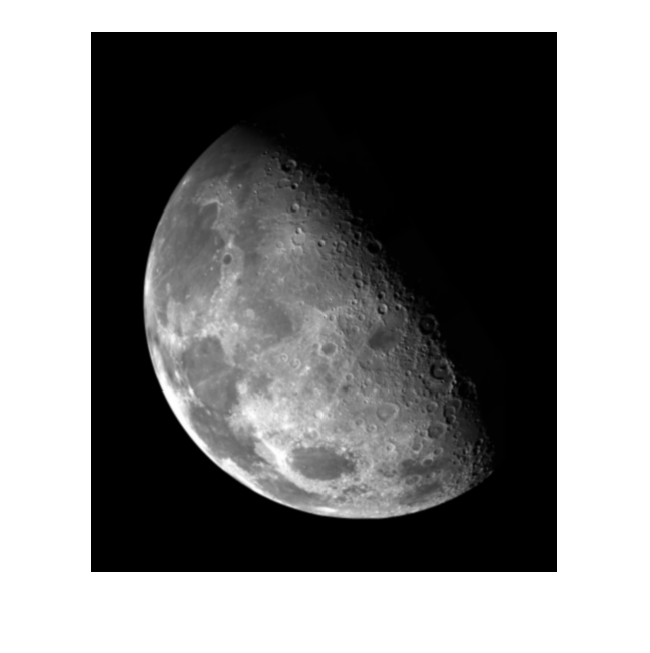

IM= imread('moon.tif');
imshow(IM);


Tmin= 60

Tmin = 60

Tmax= 140

Tmax = 140


J= (IM >Tmin & IM < Tmax); %%Given upper and lower treshhold shows the craters in the best way
imshow(J)

moonbin=imbinarize(uint8(J))

moonbin = 540×466 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


% stats = regionprops('table', moonbin,'Centroid', 'MajorAxisLength','MinorAxisLength');
% 
% centers = stats.Centroid;
% diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
% radii = diameters/2;

Rmin=10; %%radius range
Rmax=1000

Rmax = 1000


[centers, radii] = imfindcircles(moonbin,[Rmin Rmax],'ObjectPolarity','bright'); %%find ci

length(centers)

ans = 12

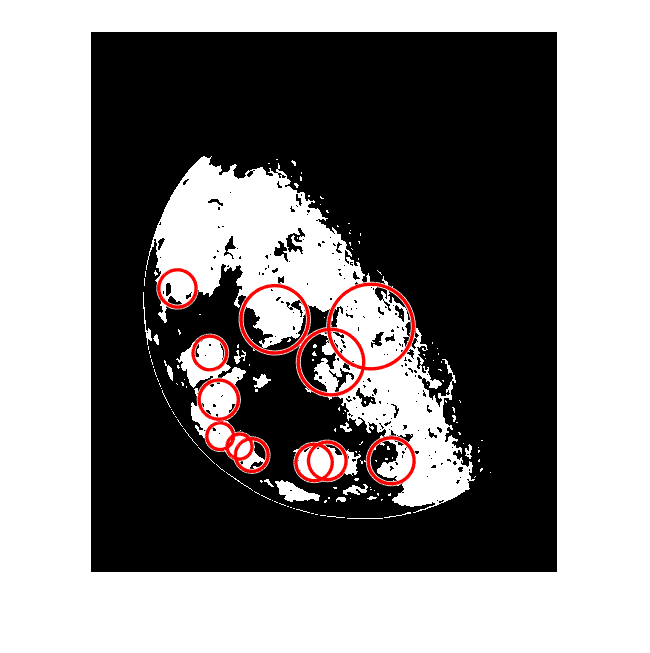



hold on
viscircles(centers,radii);
hold off